modulePath = 'C:/Users/Asus/Studia/Projekt IPS/dane - semestr 5/MATLAB_project/python_modules';
insert(py.sys.path, int32(0), modulePath);
load("C:\Users\Asus\Studia\Projekt IPS\dane - semestr 5\MATLAB_project\ab_diff_zestaw.mat")

function SARIMA_A514 = model_A5(A5)
    A51 = A5(:,1);
    SARIMA_A514 = arima('Constant',NaN,'ARLags',1:2,'D',0,'MALags',[1,2],'SARLags',[21,42],'Seasonality',21,'SMALags',[21,42],'Distribution','Gaussian');
    SARIMA_A514 = estimate(SARIMA_A514,A51,'Display','off');
end

% Wzór R2_1 (Standardowy Współczynnik Determinacji)
R2_classic = @(y_true, y_pred) 1 - (sum((y_true(:) - y_pred(:)).^2) / sum((y_true(:) - mean(y_true(:))).^2));

% Wzór R2_2 (Frakcja Wyjaśnionej Wariancji)
R2_alt = @(y_true, y_pred) sum((y_pred(:) - mean(y_true(:))).^2) / sum((y_true(:) - mean(y_true(:))).^2);

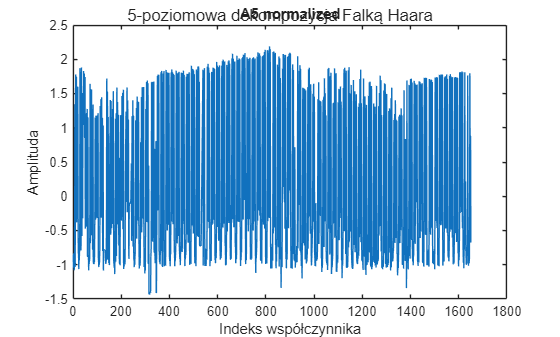

% ZBIÓR TRENINGOWY
[c, l] = wavedec(ab_diff_train_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji A i szczegółów D
A1 = appcoef(c, l, 'haar', 1);
A5 = appcoef(c, l, 'haar', 5);

D5 = detcoef(c, l, 5);
D4 = detcoef(c, l, 4);
D3 = detcoef(c, l, 3);
D2 = detcoef(c, l, 2);
D1 = detcoef(c, l, 1);

% normalizacja współczynników
[D1_norm, center_D1, scale_D1] = normalize(D1);
[A5_norm, center_A5, scale_A5] = normalize(A5);

% 2. RYSOWANIE WYKRESÓW
plot(A5_norm);
title('A5 normalized');
xlabel('Indeks współczynnika');
ylabel('Amplituda');
sgtitle('5-poziomowa dekompozycja Falką Haara');


% TEST
[c_test, l_test] = wavedec(ab_diff_test_norm, 5, 'Haar');

% Pobierz współczynniki aproksymacji (Trend) z poziomu 5
A1_test = appcoef(c_test, l_test, 'haar', 1);
A5_test = appcoef(c_test, l_test, 'haar', 5);

D5_test = detcoef(c_test, l_test, 5);
D4_test = detcoef(c_test, l_test, 4);
D3_test = detcoef(c_test, l_test, 3);
D2_test = detcoef(c_test, l_test, 2);
D1_test = detcoef(c_test, l_test, 1);

% Normalizacja współczynników testowych
D1_test_norm = (D1_test - center_D1) ./ scale_D1;
A5_test_norm = (A5_test - center_A5) ./ scale_A5;

dlugosc_testu_oryginalna = 2880; % Horyzont w oryginalnej dziedzinie czasu (2880 próbek)

dlugosc_testu_A5 = ceil(dlugosc_testu_oryginalna / 32);

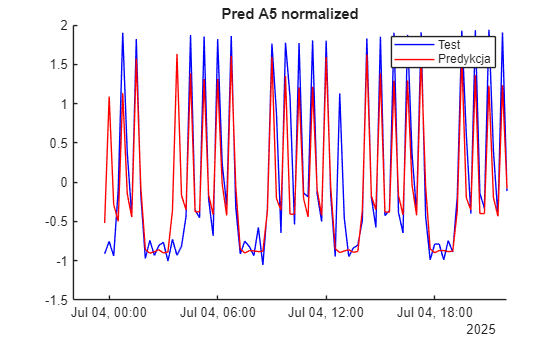

% Przewidywania A5 - model SARIMA
Mdl_A5 = model_A5(A5_norm);
A5_pred_norm = forecast(Mdl_A5, dlugosc_testu_A5, 'Y0', A5_norm);

% Narysuj wykres
figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_A5), A5_test_norm(1:dlugosc_testu_A5), 'Color','blue', 'DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_A5), A5_pred_norm, 'Color','red','DisplayName','Predykcja');
title('Pred A5 normalized');
legend;

% DENORMALIZACJA
% Odwracamy proces: x = y * scale + center
A5_pred = (A5_pred_norm .* scale_A5) + center_A5;

% Obliczamy długości wektorów dla brakujących poziomów (dla zadanego horyzontu)
len_A5 = length(A5_pred);
len_D5 = len_A5;      % Z własności Haara
len_D4 = len_A5 * 2;
len_D3 = len_A5 * 4;
len_D2 = len_A5 * 8;
len_D1 = len_A5 * 16;

% Budowa wektora c_pred
c_pred = [
    A5_pred;              % Predykcja SARIMA
    zeros(len_D5, 1);     % D5 - zerujemy
    zeros(len_D4, 1);     % D4 - zerujemy
    zeros(len_D3, 1);     % D3 - zerujemy
    zeros(len_D2, 1);     % D2 - zerujemy
    zeros(len_D1, 1);     % D1 - zerujemy
];

total_len = length(c_pred);
l_pred = [
    length(A5_pred);
    length(A5_pred);      % D5
    length(A5_pred)*2;    % D4
    length(A5_pred)*4;    % D3
    length(A5_pred)*8;    % D2
    length(A5_pred)*16;   % D1
    length(A5_pred)*32    % Całkowita długość sygnału
];

final_prediction = waverec(c_pred, l_pred, 'haar');      % podejście: A5 SARIMA
y_test = ab_diff_test_norm(1:length(final_prediction))';

mae_score = mae(y_test, final_prediction')

mae_score = 0.2090

mape_score = mape(y_test, final_prediction')

mape_score = 70.8430

rmse_score = rmse(y_test, final_prediction')

rmse_score = 0.2578

r2_classic = R2_classic(y_test, final_prediction')

r2_classic = 0.4456

r2_alt = R2_alt(y_test, final_prediction')

r2_alt = 0.4148

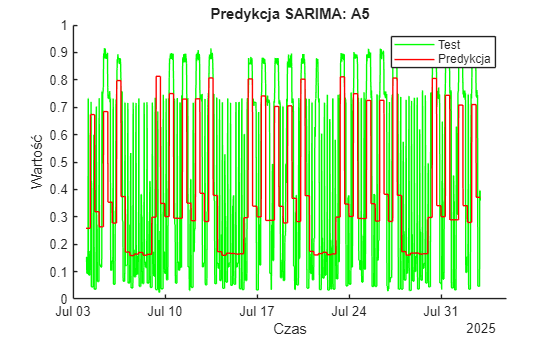


figure;
hold on;
plot(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ab_diff_test_norm(1:dlugosc_testu_oryginalna), 'Color','green','DisplayName','Test');
plot(ab_diff_test.Time(1:dlugosc_testu_oryginalna), final_prediction, 'Color','red','DisplayName','Predykcja');
xlabel('Czas');
ylabel('Wartość');
title("Predykcja SARIMA: A5")
legend;

% Tworzenie tabeli z czasem, danymi i predykcją
T_z_czasem = table(ab_diff_test.Time(1:dlugosc_testu_oryginalna), ...
                   ab_diff_test_norm(1:dlugosc_testu_oryginalna), ...
                   final_prediction(1:dlugosc_testu_oryginalna), ...
    'VariableNames', {'Czas', 'Dane_Prawdziwe', 'Predykcja'});

writetable(T_z_czasem, 'pred_ab_A5_SARIMA_month.xlsx');